# Señales y sistemas

## Explicacion: function handle vs Symbolic.



syms t
y_1=cos(t)

$$y\_1 = \cos\left(t\right)$$

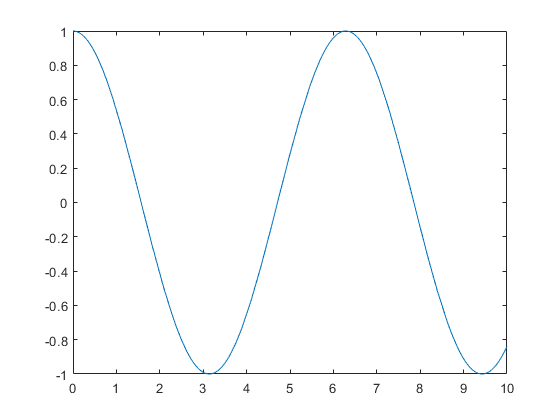

%fplot es para funciones simbolicas.
figure
fplot(y_1,[0,10])

%tambien se puede usar "function handle".
y_2= @(t) cos(t)

y_2 = function_handle with value:
    @(t)cos(t)


figure 
fplot(y_2,[0,10])

%Diferencias entre variables simbolicas y function handle.
y_2([5,10,8]) %Se evaluan directamente.

ans =     0.2837   -0.8391   -0.1455


subs(y_1,t,[5,10,8]) %Error, no se evaluan directamente, se utiliza function subs().

$$ans = \left(\begin{array}{ccc} \cos\left(5\right) & \cos\left(10\right) & \cos\left(8\right) \end{array}\right)$$

%Ventaja simbólicas: Se puede hacer algebra con variables simbólicas.
%Con function handle no se puede hacer algebra.
y_3=y_1+sin(t)+exp(-t)

$$y\_3 = {\mathrm{e}}^{-t}+\cos\left(t\right)+\sin\left(t\right)$$

diff(y_3)

$$ans = \cos\left(t\right)-{\mathrm{e}}^{-t}-\sin\left(t\right)$$

int(y_3,[0,1])

$$ans = \sin\left(1\right)-{\mathrm{e}}^{-1}-\cos\left(1\right)+2$$

## Ejercicio: Continuas vs discretas.

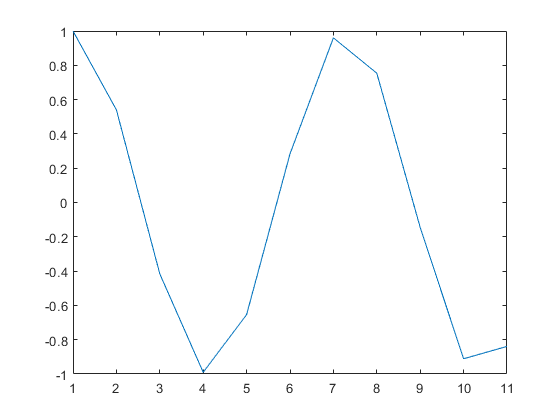

t_dsc=0:10; %para que no aparezca el valor, al correr el programa, se usa el símbolo ";"
y_dsc=y_2(t_dsc);
figure
%plot se utiliza en este caso, para muestras y vectores.
plot(y_dsc)

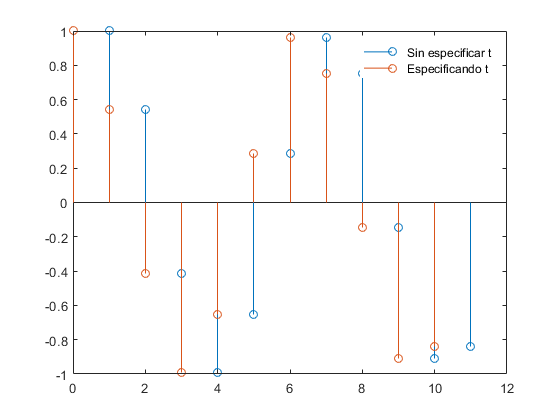


%stem para "stem and leaf plot"
stem(y_dsc)
hold on
stem(t_dsc,y_dsc)
hold off
legend("Sin especificar t","Especificando t")

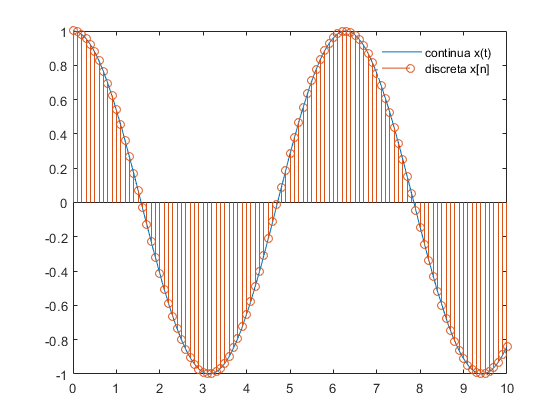


t_dsc=0:0.1:10;
y_dsc=y_2(t_dsc);          
figure
fplot(y_2,[0,10])        %grafica de funcion continua cos(t).
hold on
stem(t_dsc,y_dsc)        %grafica cos[n] para valores discretos.
hold off
legend("continua x(t)","discreta x[n]")

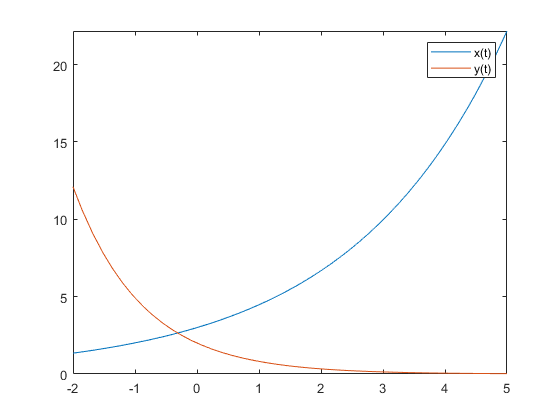

syms t
y_1=3*exp(0.40*t);         %se define la funcion x(t)
y_2=2*exp(-0.9*t);        %se define la funcion y(t)
figure
fplot(y_1,[-2,5])
hold on
fplot(y_2,[-2,5])
hold off
legend("x(t)","y(t)")

syms t
a=3

a = 3

b=2

b = 2

y_3=(a*cos(t)+b*sin(3*t))  %funcion general a*sin(t)+b*cos(t).

$$y\_3 = 2\,\sin\left(3\,t\right)+3\,\cos\left(t\right)$$

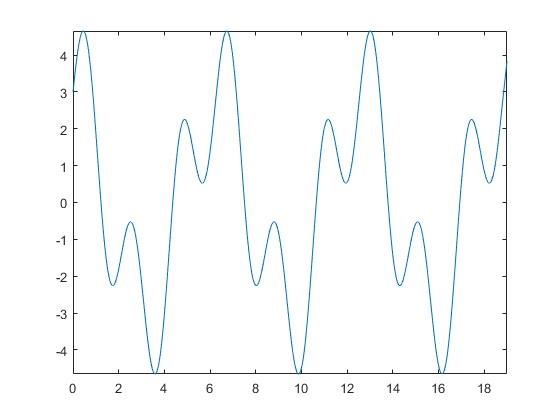


figure
fplot(y_3,[0,19])

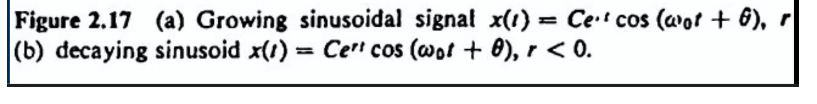

syms t
C=1;
o_0=100;
q=5;
r=-1

r = -1

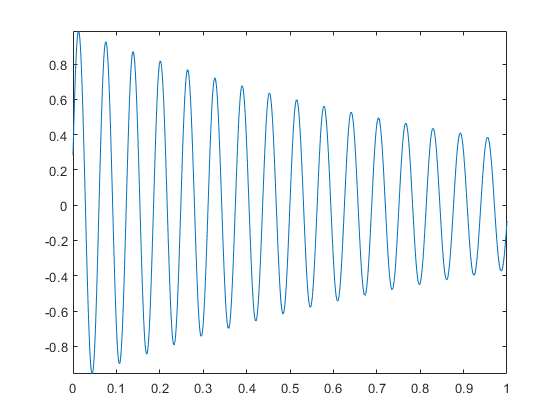

y_t=C*exp(r*t)*cos(o_0*t+q);
figure
fplot(y_t,[0,1])